# 调节器设计

note1讨论了利用状态进行反馈的控制律设计。由于系统的实际状态不一定完全可知，note2补充介绍了状态估计器。因此，我们利用状态估计值进行反馈即可实现系统稳定。为了说明这种做法的可行性，我们做如下证明：

设系统状态空间表达式为：$\[\left\{ {\begin{array}{*{20}{l}}
  {{\mathbf{\dot x}} = {\mathbf{Ax}} + {\mathbf{B}}u} \\ 
  {y = {\mathbf{Cx}} } 
\end{array}} \right.\]$

相应状态估计器为：$\[{\bf{\dot \hat x}} = \left( {{\bf{A}} - {\bf{LC}}} \right){\bf{\hat x}} + {\bf{B}}u + {\bf{L}}y\]$

考虑控制律由状态估计值组合：$u=-\mathbf{K}\hat{\mathbf{x}}$

联立上式，可以得到整个系统的状态空间方程为：$\[\left[ {\begin{array}{*{20}{c}}
{{\bf{\dot x}}}\\
{{\bf{\dot \hat x}}}
\end{array}} \right] = \left[ {\begin{array}{*{20}{c}}
{\bf{A}}&{ - {\bf{BK}}}\\
{{\bf{LC}}}&{{\bf{A}} - {\bf{LC}} - {\bf{BK}}}
\end{array}} \right]\left[ {\begin{array}{*{20}{c}}
{\bf{x}}\\
{{\bf{\hat x}}}
\end{array}} \right]\]$

考察整个系统矩阵的特征值（极点）：$\[\left| {\begin{array}{*{20}{c}}
{\bf{A}}&{ - {\bf{BK}}}\\
{{\bf{LC}}}&{{\bf{A}} - {\bf{LC}} - {\bf{BK}}}
\end{array}} \right| = \left| {\begin{array}{*{20}{c}}
{\bf{A}}&{ - {\bf{BK}}}\\
{{\bf{LC}} - {\bf{A}}}&{{\bf{A}} - {\bf{LC}}}
\end{array}} \right| = \left| {\begin{array}{*{20}{c}}
{{\bf{A}} - {\bf{BK}}}&{ - {\bf{BK}}}\\
{\bf{0}}&{{\bf{A}} - {\bf{LC}}}
\end{array}} \right| = \left| {{\bf{A}} - {\bf{BK}}} \right|\left| {{\bf{A}} - {\bf{LC}}} \right|\]$

上式表明整个系统的极点就是理想状态反馈和状态估计器的极点的集合。

因此引入现代控制常用的**分离原理**：控制器和估计器可单独设计，他们分别稳定时系统一定稳定。

下面我们以一个经典的负弹簧为例介绍调节器设计。

## 负弹簧调节器设计

设有一负弹簧系统，其等效的自然频率为：$\omega_n=2 \ \rm rad/s$，该系统状态空间可表示为：$\[\left\{ {\begin{array}{*{20}{l}}
{{\bf{\dot x}} = \left[ {\begin{array}{*{20}{c}}
0&1\\
{\omega _n^2}&0
\end{array}} \right]{\bf{x}} + \left[ {\begin{array}{*{20}{c}}
0\\
1
\end{array}} \right]u}\\
{y = \left[ {\begin{array}{*{20}{c}}
1&0
\end{array}} \right]{\bf{x}}}
\end{array}} \right.\]
$。

控制律设计可参考note0，将极点配置在：$-0.5\pm0.866j$，（$\omega_n=1 {\rm \ rad/s, \ } \zeta=0.5$）；

为加快状态估计器收敛，将估计器极点配置在：$-3.5\pm3.571j$，（$\omega_n=5 {\rm \ rad/s, \ } \zeta=0.7$）。

仿真模型见model2，零输入响应如下图所示：

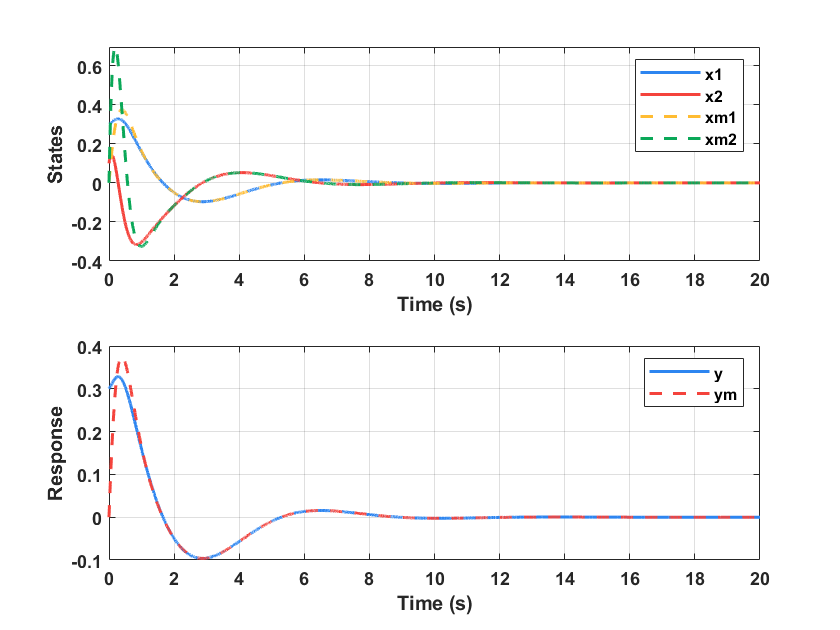

set(groot,'DefaultLineLineWidth',1.5)
set(groot,'DefaultAxesFontSize',10)
set(groot,'DefaultFigureColor','w')
set(groot,'DefaultAxesFontWeight','bold')
close all
clear;clc

T = 20;
Ts = 1e-3;
x0 = [0.3 0.1]';

omgn = 2;
A = [0 1; omgn^2 0];
B = [0 1]';
C = [1 0];

% Control Law
K = place(A,B,[-0.5+0.866j -0.5-0.866j]);

% State Estimator
L = place(A',C',[-3.5+3.571j -3.5-3.571j]);
L = L';

sim('model2_RegulatorDesign.slx')

figure
subplot(2,1,1)
plot(t,x)
hold on
grid on
plot(t,xm,'--')
xlabel('Time (s)')
ylabel('States')
legend('x1','x2','xm1','xm2')

subplot(2,1,2)
plot(t,y)
hold on
grid on
plot(t,ym,'--')
xlabel('Time (s)')
ylabel('Response')
legend('y','ym')

仿真可以看出，估计的状态收敛于实际状态，估计器的输出收敛于实际的输出。

利用该调节器，可以使各状态/输出最后收敛到零位。